# **3. MEASURING THE EFFECT OF A SUGAR TAX**

## **PART 3.1**

% start fresh
clc, clearvars, close all

% import data set

% Set up the Import Options and import the data
opts = spreadsheetImportOptions("NumVariables", 12);

% Specify sheet and range
opts.Sheet = "Data";
opts.DataRange = "A2:L2176";

% Specify column names and types
opts.VariableNames = ["store_id", "type", "store_type", "type2", "size", "price", "price_per_oz", "price_per_oz_c", "taxed", "supp", "time", "product_id"];
opts.VariableTypes = ["double", "categorical", "double", "categorical", "double", "double", "double", "double", "double", "double", "categorical", "double"];

% Specify variable properties
opts = setvaropts(opts, ["type", "type2", "time"], "EmptyFieldRule", "auto");

% Import the data
tempdata1 = readtable("C:\Users\HP\Doing Economics\MATLAB\Project 3\/Dataset Project 3.xlsx", opts, "UseExcel", false);

% Clear temporary variables
clear opts

% Display results
tempdata1

tempdata1 = 2175×12 table
    store_id      type       store_type       type2        size    price    price_per_oz    price_per_oz_c    taxed    supp     time      product_id
    ________    _________    __________    ____________    ____    _____    ____________    ______________    _____    ____    _______    __________

       16       WATER            2         <undefined>     33.8    1.69           0.05               5          0       0      DEC2014        29    
       16       TEA              2         <undefined>       23    0.99       0.043043          4.3043          1     

% examine data set
summary(tempdata1);

Variables:

    store_id: 2175×1 double

        Values:

            Min           1   
            Median       14   
            Max          26   

    type: 2175×1 categorical

        Values:

            ENERGY           163   
            ENERGY-DIET      138   
            JUICE            186   
            JUICE DRINK       42   
            MILK             177   
            SODA             716   
            SODA-DIET        429   
            SPORT             39   
            SPORT-DIET         4   
            TEA              138   
            TEA-DIET          20   
            WATER            120   
            WATER-SWEET        3   

    store_type: 2175×1 double

        Values:

            Min          1    
            Median       2    
            Max          4    

    type2: 2175×1 categorical

        Values:

            COCONUT WATER        69  
            LOW FAT MILK         63 

% format data appropriately
tempdata1.store_id = categorical(tempdata1.store_id);
tempdata1.store_type = categorical(tempdata1.store_type);
tempdata1.store_type(tempdata1.store_type == '1') = 'Large Supermarket';
tempdata1.store_type(tempdata1.store_type == '2') = 'Small Supermarket';
tempdata1.store_type(tempdata1.store_type == '3') = 'Pharmacy';
tempdata1.store_type(tempdata1.store_type == '4') = 'Gas Station';
tempdata1.taxed = categorical(tempdata1.taxed);
tempdata1.taxed(tempdata1.taxed == '0') = 'Nontaxed';
tempdata1.taxed(tempdata1.taxed == '1') = 'Taxed';
tempdata1.supp = categorical(tempdata1.supp);
tempdata1.supp(tempdata1.supp == '0') = 'Standard';
tempdata1.supp(tempdata1.supp == '1') = 'Supplemental';
tempdata1.time(tempdata1.time == 'MAR2015') = 'MAR2016';
tempdata1.product_id = categorical(tempdata1.product_id);

% ensure correctness of formatting
summary(tempdata1);

Variables:

    store_id: 2175×1 categorical

        Values:

            1        62   
            2        89   
            3       158   
            4        94   
            5        83   
            6        71   
            7         9   
            8        75   
            9       111   
            10      120   
            11       54   
            12       30   
            13       66   
            14       93   
            15      133   
            16      132   
            17       93   
            18       20   
            19       79   
            20      129   
            21       40   
            22       44   
            23       94   
            24       93   
            25      133   
            26       70   

    type: 2175×1 categorical

        Values:

            ENERGY           163   
            ENERGY-DIET      138   
            JUICE            186   
            JUICE DRINK       42   
         

% calculate number of unique products and stores
products = length(unique(tempdata1.product_id));
stores = length(unique(tempdata1.store_id));
fprintf('no. of unique products: %i\nno. of unique stores: %i', products, stores);

no. of unique products: 247
no. of unique stores: 26

% make frequency table for store_type across time
tcounts1 = varfun(@(x) length(x), tempdata1, 'GroupingVariables', {'store_type' 'time'}, 'InputVariables', {});
tcrosstab1 = unstack(tcounts1, 'GroupCount', 'time');
tcrosstab1.Properties.RowNames = cellstr(tcrosstab1.store_type);
tcrosstab1.store_type = [];
disp(tcrosstab1);

                         DEC2014    JUN2015    MAR2016
                         _______    _______    _______

    Large Supermarket      177        209        158  
    Small Supermarket      407        391        327  
    Pharmacy                87        102         73  
    Gas Station             73         96         75  



% make frequency table for store_type across taxed in DEC2014
tcounts2 = varfun(@(x) length(x), tempdata1(tempdata1.time == 'DEC2014', :), 'GroupingVariables', {'store_type' 'taxed'}, 'InputVariables', {});
tcrosstab2 = unstack(tcounts2, 'GroupCount', 'taxed');
tcrosstab2.Properties.RowNames = cellstr(tcrosstab2.store_type);
tcrosstab2.store_type = [];
disp(tcrosstab2);

                         Nontaxed    Taxed
                         ________    _____

    Large Supermarket       92         85 
    Small Supermarket      196        211 
    Pharmacy                44         43 
    Gas Station             34         39 



% make frequency table for store_type across taxed in JUN2015
tcounts3 = varfun(@(x) length(x), tempdata1(tempdata1.time == 'JUN2015', :), 'GroupingVariables', {'store_type' 'taxed'}, 'InputVariables', {});
tcrosstab3 = unstack(tcounts3, 'GroupCount', 'taxed');
tcrosstab3.Properties.RowNames = cellstr(tcrosstab3.store_type);
tcrosstab3.store_type = [];
disp(tcrosstab3);

                         Nontaxed    Taxed
                         ________    _____

    Large Supermarket      111         98 
    Small Supermarket      192        199 
    Pharmacy                52         50 
    Gas Station             44         52 



% make frequency table for store_type across taxed in MAR2016
tcounts4 = varfun(@(x) length(x), tempdata1(tempdata1.time == 'MAR2016', :), 'GroupingVariables', {'store_type' 'taxed'}, 'InputVariables', {});
tcrosstab4 = unstack(tcounts4, 'GroupCount', 'taxed');
tcrosstab4.Properties.RowNames = cellstr(tcrosstab4.store_type);
tcrosstab4.store_type = [];
disp(tcrosstab4);

                         Nontaxed    Taxed
                         ________    _____

    Large Supermarket       88         70 
    Small Supermarket      154        173 
    Pharmacy                36         37 
    Gas Station             31         44 



% make frequency table for store_type across taxed
tcounts5 = varfun(@(x) length(x), tempdata1, 'GroupingVariables', {'store_type' 'taxed'}, 'InputVariables', {});
tcrosstab5 = unstack(tcounts5, 'GroupCount', 'taxed');
tcrosstab5.Properties.RowNames = cellstr(tcrosstab5.store_type);
tcrosstab5.store_type = [];
disp(tcrosstab5);

                         Nontaxed    Taxed
                         ________    _____

    Large Supermarket      291        253 
    Small Supermarket      542        583 
    Pharmacy               132        130 
    Gas Station            109        135 



% make frequency table for type across time
tcounts6 = varfun(@(x) length(x), tempdata1, 'GroupingVariables', {'type' 'time'}, 'InputVariables', {});
tcrosstab6 = unstack(tcounts6, 'GroupCount', 'time');
tcrosstab6.Properties.RowNames = cellstr(tcrosstab6.type);
tcrosstab6.type = [];
disp(tcrosstab6);

                   DEC2014    JUN2015    MAR2016
                   _______    _______    _______

    ENERGY            56         58         49  
    ENERGY-DIET       49         54         35  
    JUICE             70         64         52  
    JUICE DRINK       19         17          6  
    MILK              63         61         53  
    SODA             239        262        215  
    SODA-DIET        128        174        127  
    SPORT             11         16         12  
    SPORT-DIET         2          2        NaN  
    TEA               52         45         41  
    TEA-DIET           6          6          8  
    WATER             48         38         34  
    

% get list of product and store ids
pid_list = unique(tempdata1.product_id);
sid_list = unique(tempdata1.store_id);

for i = 1:length(pid_list)
  for j = 1:length(sid_list)
    % pick product-store combination
    temp = tempdata1(tempdata1.product_id == int2str(i) & tempdata1.store_id == int2str(j), :);
    temp_time = temp.time;
    % create boolean for whether current combination exists in each time period
    test = (any(temp_time == 'DEC2014') & any(temp_time == 'JUN2015') & any(temp_time == 'MAR2016'));
    % assign boolean to current combination
    tempdata1.period_test(tempdata1.product_id == pid_list(i) & tempdata1.store_id == sid_list(j)) = test;
  end
end

% create subtable for combinations found in each time period
tempdata2 = tempdata1(tempdata1.period_test == 1 & tempdata1.supp == 'Standard', :)

tempdata2 = 939×13 table
    store_id       type           store_type           type2        size    price    price_per_oz    price_per_oz_c     taxed        supp       time      product_id    period_test
    ________    ___________    _________________    ____________    ____    _____    ____________    ______________    ________    ________    _______    __________    ___________

       16       WATER          Small Supermarket    <undefined>     33.8    1.69           0.05               5        Nontaxed    Standard    DEC2014       29            t

% calculate mean price based on grouped data
tempdata3 = groupsummary(tempdata2, {'taxed' 'store_type' 'time'}, 'mean', 'price_per_oz')

tempdata3 = 24×5 table
     taxed         store_type         time      GroupCount    mean_price_per_oz
    ________    _________________    _______    __________    _________________

    Nontaxed    Large Supermarket    DEC2014        36             0.11192     
    Nontaxed    Large Supermarket    JUN2015        36              0.1148     
    Nontaxed    Large Supermarket    MAR2016        36             0.11702     
    Nontaxed    Small Supermarket    DEC2014        70             0.13671     
    Nontaxed    Small Supermarket    JUN2015        70             0.13817     
    Nontaxed    Small Supermarket    MAR2016        70             0.13367     
    Nontaxed    Pharmacy             DEC2014        18             0.15196     
    Nontaxed    Pharmacy             JUN2015        18             0.16075     
    No

% create subtable grouped by only taxed and store_type
tempdata4 = unique(tempdata3(:, {'taxed' 'store_type'}));

% create subtables for each time period to allow comparisons
d14 = tempdata3(tempdata3.time == 'DEC2014', :);
j15 = tempdata3(tempdata3.time == 'JUN2015', :);
m16 = tempdata3(tempdata3.time == 'MAR2016', :);

% save differences in means
tempdata4.d1 = j15.mean_price_per_oz - d14.mean_price_per_oz;
tempdata4.d2 = m16.mean_price_per_oz - d14.mean_price_per_oz;
tempdata4

tempdata4 = 8×4 table
     taxed         store_type            d1            d2    
    ________    _________________    __________    __________

    Nontaxed    Large Supermarket     0.0028845     0.0050956
    Nontaxed    Small Supermarket     0.0014575    -0.0030362
    Nontaxed    Pharmacy              0.0087965     0.0023951
    Nontaxed    Gas Station          0.00028995      0.001063
    Taxed       Large Supermarket      0.013122      0.010669
    Taxed       Small Supermarket     0.0014418    -0.0035851
    Taxed       Pharmacy              0.0089701     0.0044848
    Taxed       Gas Station           0.0092508    -0.0017405


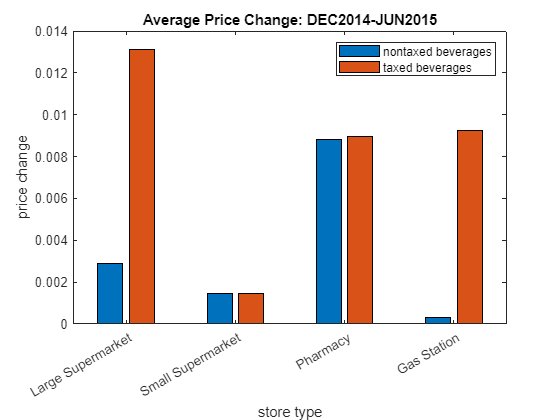

% plot difference in means of DEC2014 and JUN2015 across store types
bar([tempdata4{1, 'd1'} tempdata4{5, 'd1'}; tempdata4{2, 'd1'} tempdata4{6, 'd1'}; tempdata4{3, 'd1'} tempdata4{7, 'd1'}; tempdata4{4, 'd1'} tempdata4{8, 'd1'}]);
title('Average Price Change: DEC2014-JUN2015');
xlabel('store type');
xticklabels(tempdata4.store_type);
ylabel('price change');
legend('nontaxed beverages', 'taxed beverages', 'Location', 'northeast');

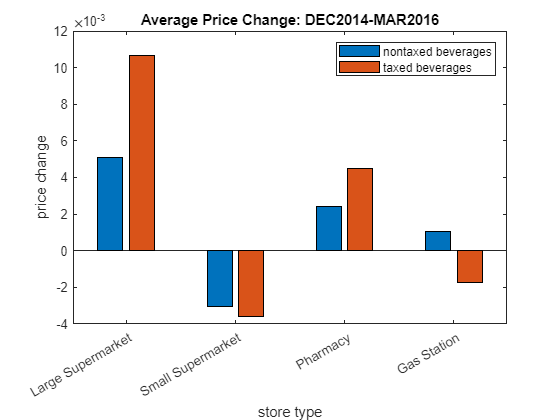

% plot difference in means of DEC2014 and MAR2016 across store types
bar([tempdata4{1, 'd2'} tempdata4{5, 'd2'}; tempdata4{2, 'd2'} tempdata4{6, 'd2'}; tempdata4{3, 'd2'} tempdata4{7, 'd2'}; tempdata4{4, 'd2'} tempdata4{8, 'd2'}]);
title('Average Price Change: DEC2014-MAR2016');
xlabel('store type');
xticklabels(tempdata4.store_type);
ylabel('price change');
legend('nontaxed beverages', 'taxed beverages', 'Location', 'northeast');

## **PART 3.2**

% import data set

% Set up the Import Options and import the data
opts2 = delimitedTextImportOptions("NumVariables", 8);

% Specify range and delimiter
opts2.DataLines = [2, Inf];
opts2.Delimiter = ",";

% Specify column names and types
opts2.VariableNames = ["year", "quarter", "month", "location", "beverage_group", "tax", "price", "under_report"];
opts2.VariableTypes = ["double", "double", "double", "categorical", "categorical", "categorical", "double", "string"];

% Specify file level properties
opts2.ExtraColumnsRule = "ignore";
opts2.EmptyLineRule = "read";

% Specify variable properties
opts2 = setvaropts(opts2, "under_report", "WhitespaceRule", "preserve");
opts2 = setvaropts(opts2, ["location", "beverage_group", "tax", "under_report"], "EmptyFieldRule", "auto");

% Import the data
tempdata5 = readtable("C:\Users\HP\Doing Economics\MATLAB\Project 3\public_use_weighted_prices2.csv", opts2);

% Clear temporary variables
clear opts2

% Display results
tempdata5

tempdata5 = 2728×8 table
    year    quarter    month      location             beverage_group              tax       price     under_report
    ____    _______    _____    ____________    ____________________________    _________    ______    ____________

    2013       1         1      Berkeley        soda                            Non-taxed    4.8534         ""     
    2013       1         1      Non-Berkeley    soda                            Non-taxed    3.5103         ""     
    2013       1         1      Non-Berkeley    soda                            Non-taxed    3.8896         ""     
    2013       1         1      Berkeley        soda                            Taxed        3.6828         ""     
    20

% examine data set
summary(tempdata5);

Variables:

    year: 2728×1 double

        Values:

            Min         2013  
            Median      2014  
            Max         2016  

    quarter: 2728×1 double

        Values:

            Min          1    
            Median       2    
            Max          4    

    month: 2728×1 double

        Values:

            Min           1   
            Median        6   
            Max          12   

    location: 2728×1 categorical

        Values:

            Berkeley           912  
            Non-Berkeley      1816  

    beverage_group: 2728×1 categorical

        Values:

            fruit drinks/flavored waters      682   
            milk                              341   
            milk substitutes                  682   
            soda                              682   
            water                             341   

    tax: 2728×1 categoric

% calculate mean price based on grouped data
tempdata6 = groupsummary(tempdata5, {'year' 'month' 'location' 'tax'}, 'mean', 'price')

tempdata6 = 156×6 table
    year    month      location         tax       GroupCount    mean_price
    ____    _____    ____________    _________    __________    __________

    2013      1      Berkeley        Non-taxed        15          5.7225  
    2013      1      Berkeley        Taxed             9          8.6928  
    2013      1      Non-Berkeley    Non-taxed        25          5.3486  
    2013      1      Non-Berkeley    Taxed            15          7.9916  
    2013      2      Berkeley        Non-taxed        15          5.8065  
    2013      2      Berkeley        Taxed             9          8.6546  
    2013      2      Non-Berkeley    Non-taxed        25          5.3639  
    2013      2      Non-Berkeley    Taxed            15          8.1809  
    2013      3      

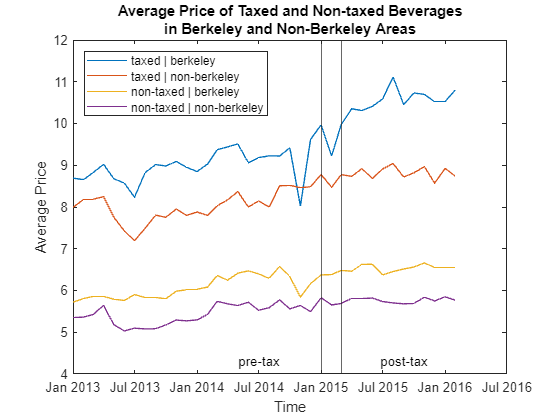

% format month variable to get a valid expression for datetime
tempdata6.month = string(num2str(tempdata6.month, '%02.f'));

% create subtables to plot separate line charts
tax_berk = tempdata6(tempdata6.location == 'Berkeley' & tempdata6.tax == 'Taxed', :);
tax_nberk = tempdata6(tempdata6.location == 'Non-Berkeley' & tempdata6.tax == 'Taxed', :);
ntax_berk = tempdata6(tempdata6.location == 'Berkeley' & tempdata6.tax == 'Non-taxed', :);
ntax_nberk = tempdata6(tempdata6.location == 'Non-Berkeley' & tempdata6.tax == 'Non-taxed', :);

% get dates to plot in a time-series fashion
dates = datetime(tax_berk.year + tax_berk.month + '01','InputFormat','yyyyMMdd');

% construct and annotate line charts
plot(dates, tax_berk.mean_price);
hold on;
plot(dates, tax_nberk.mean_price);
plot(dates, ntax_berk.mean_price);
plot(dates, ntax_nberk.mean_price);
title({'Average Price of Taxed and Non-taxed Beverages', 'in Berkeley and Non-Berkeley Areas'});
xlabel('Time');
xline([dates(25) dates(27)]);
ylabel('Average Price');
ylim([4 12]);
hold off;
text(dates(19), 4.5, 'pre-tax', 'HorizontalAlignment', 'center', 'VerticalAlignment', 'top');
text(dates(33), 4.5, 'post-tax', 'HorizontalAlignment', 'center', 'VerticalAlignment', 'top');
legend('taxed | berkeley', 'taxed | non-berkeley', 'non-taxed | berkeley', 'non-taxed | non-berkeley', 'Location', 'northwest');